preprocessed=nextracted;
preprocessed_data=preprocessed.new_case28;

preprocessed_data = struct with fields:
      eegdata: [405346×1 double]
     timedata: [405346×1 double]
      bisdata: [405346×1 double]
    heartdata: [405346×1 double]
     respdata: [405346×1 double]
       o2data: [405346×1 double]
      ecgdata: [405346×1 double]
    entropies: []
          bsr: []
     spectral: []


time_interval=20;
    fs=100;
    n_points=time_interval*fs;
    l=length(preprocessed_data.bisdata)

l = 405346

 ranger=[l-100000:l-20000];

ranger =       305346      305347      305348      305349      305350      305351      305352      305353      305354      305355      305356      305357      305358      305359      305360      305361      305362      305363      305364      305365      305366      305367      305368      305369      305370      305371      305372      305373      305374      305375      305376      305377      305378      305379      305380      305381      305382      305383      305384      305385      305386      305387      305388      305389      305390      305391      305392      305393      305394      305395




bis1=preprocessed_data.bisdata(ranger);
time=preprocessed_data.timedata(ranger)/1000;
recording_time=time(end)-time(1);

recording_time = 800.7800

   bis=zeros(round(recording_time/time_interval),1);
    for i=1:length(bis)
        range=round([(i-1)*n_points+1 :i*n_points]);
        bis(i)=mean(bis1(range));
    end

Signal=preprocessed_data.eegdata(ranger);

Signal =   -10.9181
    4.9112
   -5.9250
   -9.0565
   -6.9447
   -1.0468
   -0.9432
   -6.0413
   -1.9619
   -1.0241



sef=zeros(size(bis));
delr=zeros(size(bis));
absal=zeros(size(bis));
absdel=zeros(size(bis));
    for i=1:length(bis)   
        range=round([(i-1)*n_points+1 :i*n_points]);
        [sef(i),delr(i),absdel(i),absal(i)]=getPowerSpecVal(Signal(range),fs);
    end

    
    corrcoef(sef,bis)

ans =     1.0000   -0.2605
   -0.2605    1.0000


    corrcoef(delr,bis)

ans =     1.0000   -0.0907
   -0.0907    1.0000


    corrcoef(absdel,bis)

ans =     1.0000   -0.5467
   -0.5467    1.0000


    corrcoef(absal,bis)

ans =     1.0000   -0.3190
   -0.3190    1.0000


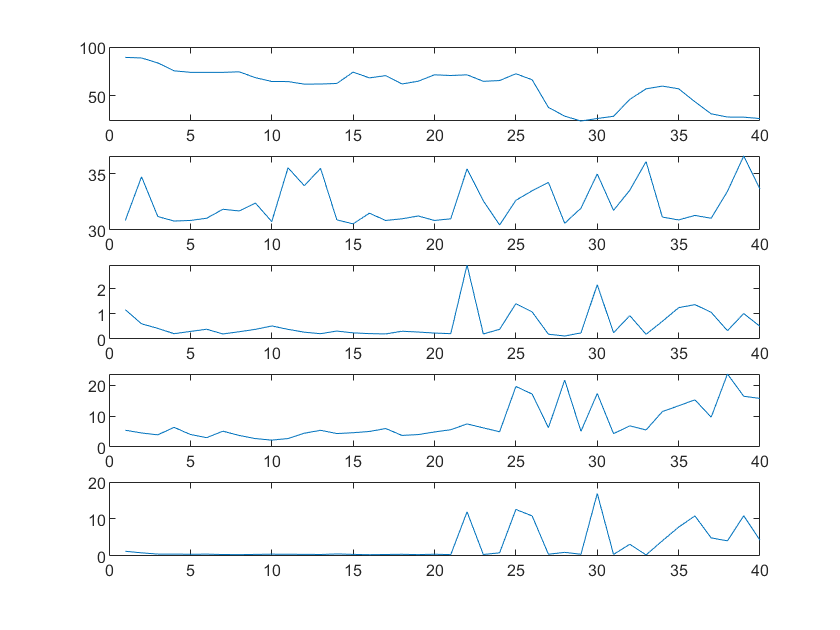

    subplot(511)
    plot(bis)
    subplot(512)
    plot(sef)
    subplot(513)
    plot(delr)
    subplot(514)
    plot(absdel)
    subplot(515)
    plot(absal)

% fs = 100;
% t = 0:0.01:20;
% %eeg = cos(2*pi*t'*20)+0.1*randn(size(t'));
% l=length(unprocessed_data.eegdata)-1000000

Unable to resolve the name unprocessed_data.eegdata.

% EEG=unprocessed_data.eegdata(l-10000:l,1)';
% plot(EEG)
% [s,d,ad,aa]=getPowerSpecVal(EEG,fs)
% %{
% EEG=unprocessed_data.eegdata(l-8000:l,1)';
% plot(EEG)
% [s,d,ad,aa]=getPowerSpecVal(EEG,Fs)
% EEG=unprocessed_data.eegdata(l-4000:l,1)';
% plot(EEG)
% [s,d,ad,aa]=getPowerSpecVal(EEG,Fs)
% %}
% EEG=unprocessed_data.eegdata(l-2000:l,1)';
% plot(EEG)
% [s,d,ad,aa]=getPowerSpecVal(EEG,fs)

l=length(unprocessed_data.eegdata)
EEG=unprocessed_data.eegdata(l-2000:l,1)';
plot(EEG)
[s,d,ad,aa]=getPowerSpecVal(EEG,fs)

function [sef90,delratio,absdelta,absalpha] = getPowerSpecVal(eeg,Fs)
    absdelta=bandpower(eeg,Fs,[0 4]);
    absalpha=bandpower(eeg,Fs,[8 13]);
    delratio=bandpower(eeg,Fs,[8 30])/bandpower(eeg,Fs,[0 4]);
    
    %%SEF calculation
    eeglp=bandpass(eeg,[1,30],Fs);
    L=length(eeglp);
    f_domain=abs(fft(eeglp))/L;
    f_domain=f_domain(1:L/2).^2;
    total_power=sum(f_domain);
    temp_power=0;
    for i=1:L
        temp_power=temp_power+f_domain(i);
        if(temp_power/total_power>=0.9)
            sef90=i*Fs/L;
            break
        end
    end
    

end